human = getgenbank('NC_012920','SequenceOnly',true);

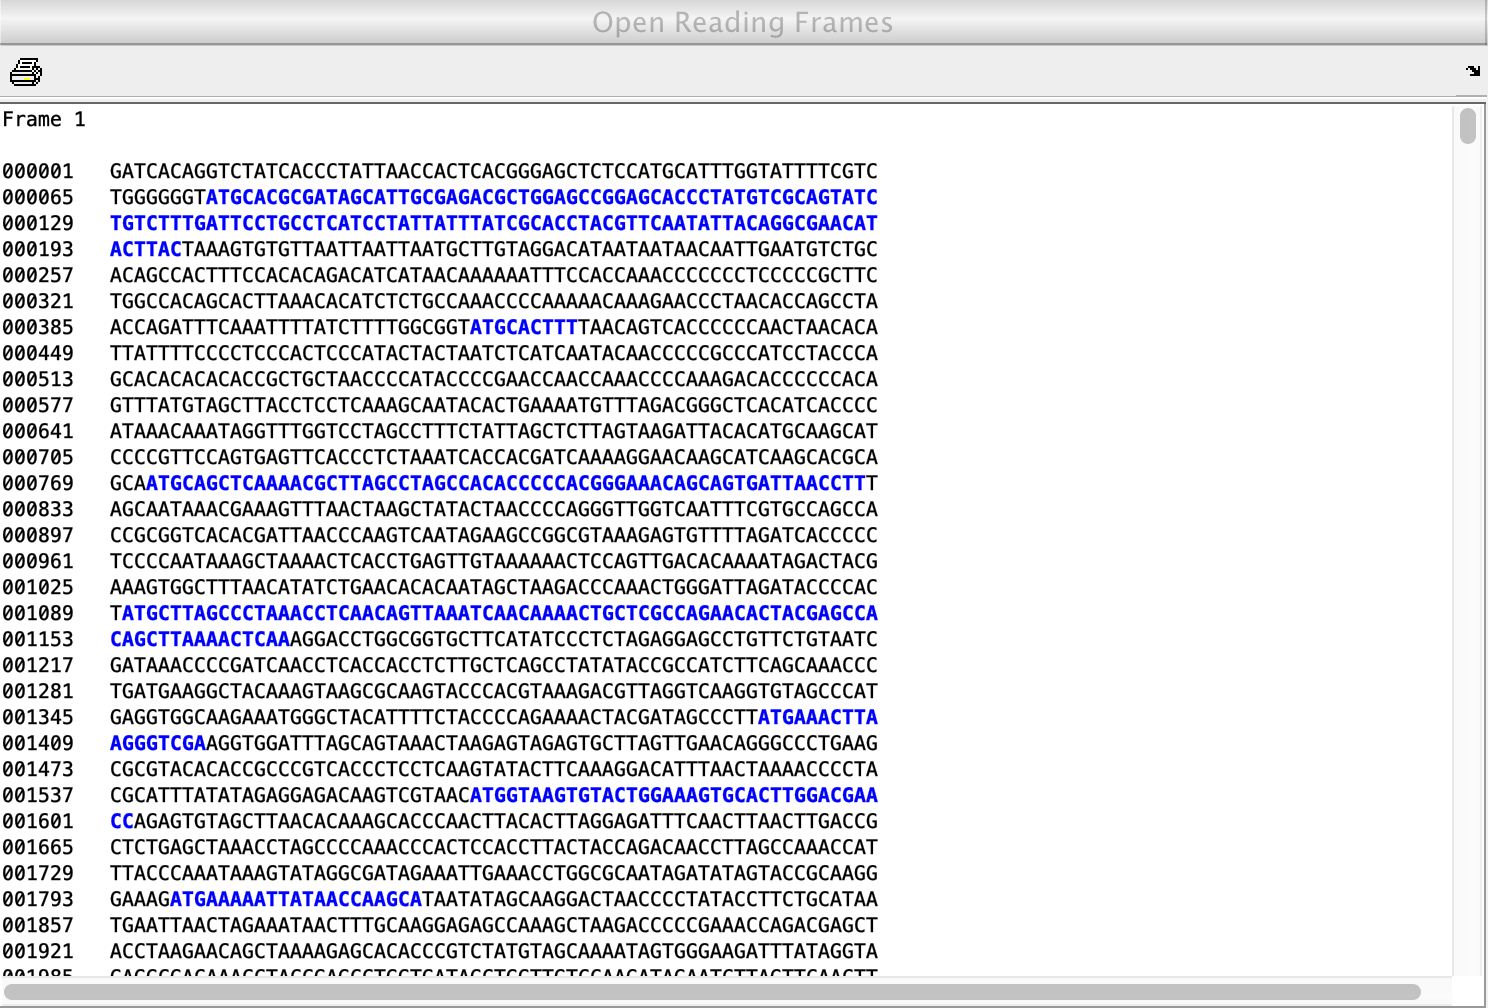

h_orf = seqshoworfs(human,'MINIMUMLENGTH',1, 'geneticcode',2,'frames','all');

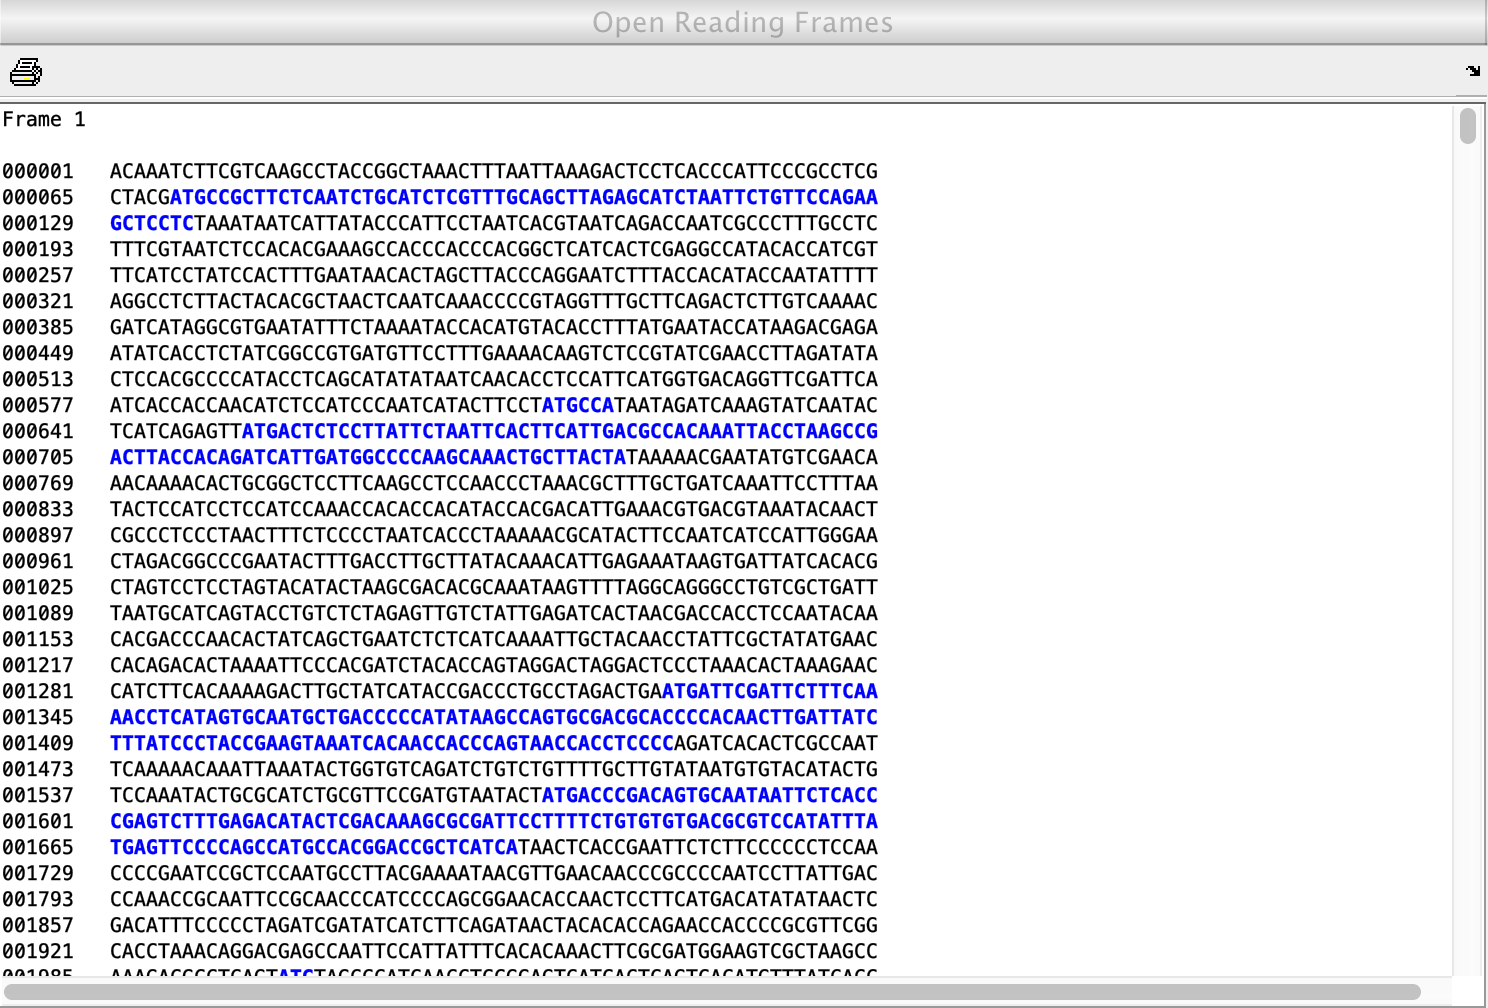

h_orf1= seqshoworfs(human(randperm(length(human))),'MINIMUMLENGTH',1,'geneticcode',2,'frames','all');

h_ORFLength=[];
for i=1:6
   for j=1:length(h_orf(i).Stop)
    h_ORFLength=[h_ORFLength; h_orf(i).Stop(j)+2 - h_orf(i).Start(j)];
   end
end
length(h_ORFLength)

ans = 435

h_ORFLength1=[];
for i=1:6
   for j=1:length(h_orf1(i).Stop)
    h_ORFLength1=[h_ORFLength1; h_orf1(i).Stop(j)+2 - h_orf1(i).Start(j)];
   end
end
length(h_ORFLength1)

ans = 446

h_max_threshold=max(h_ORFLength1)

h_max_threshold = 404

h_n_max=length(find(h_ORFLength>=h_max_threshold))

h_n_max = 11

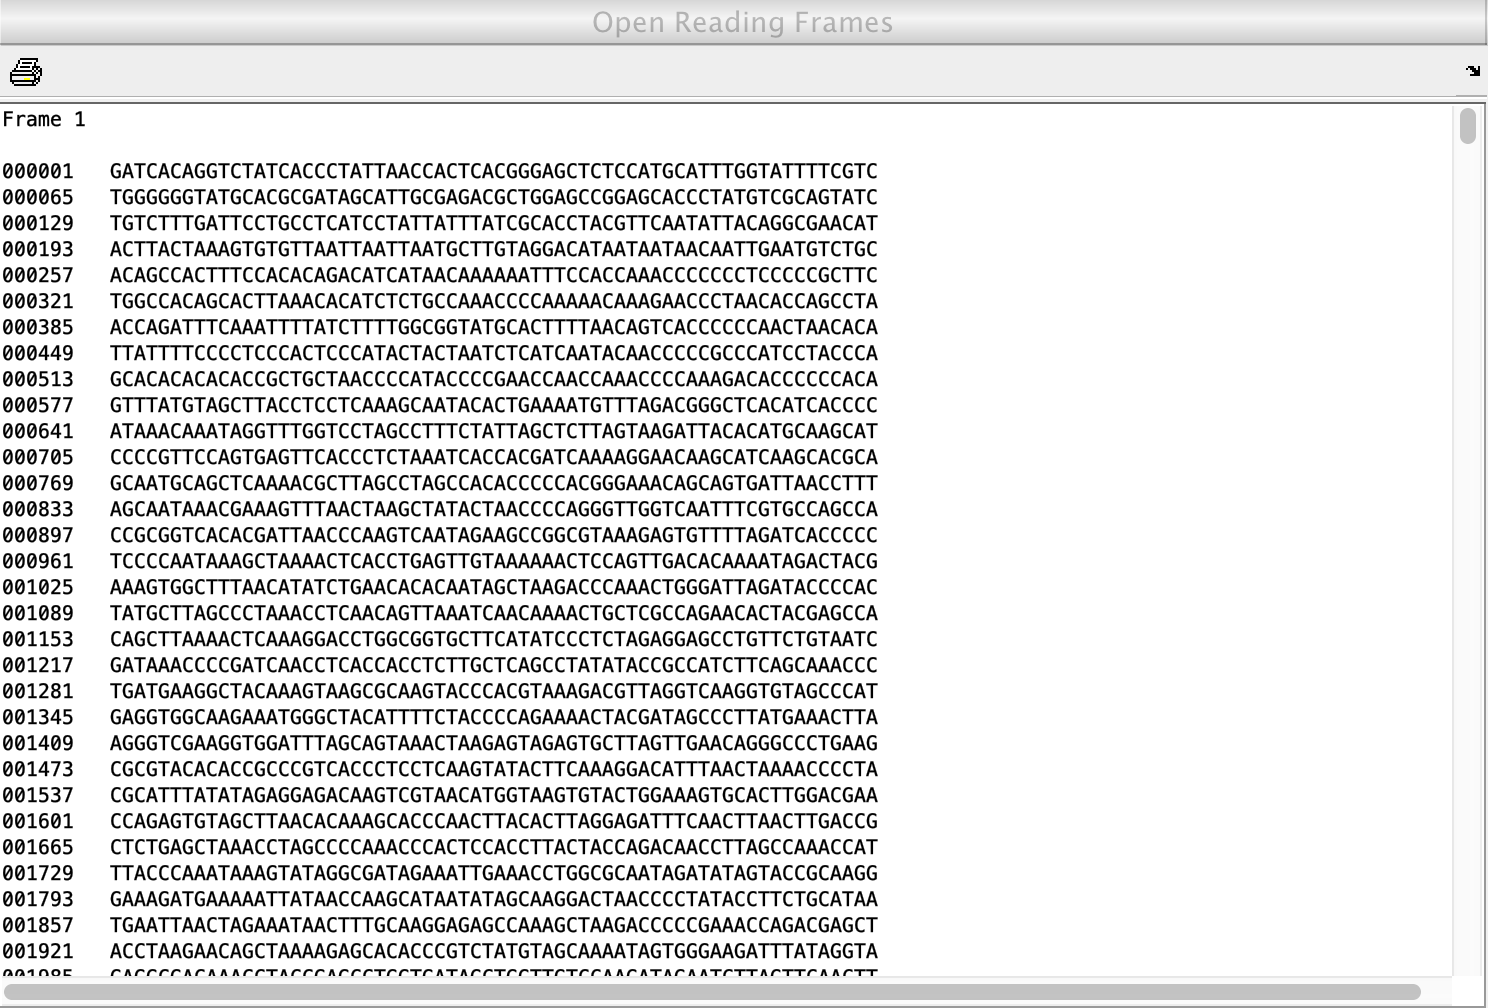

h_orf_threshold = seqshoworfs(human,'MINIMUMLENGTH',h_max_threshold/3, 'geneticcode',2,'frames','all');

h_orfNew=[];
for i=1:6
    for j=1:length(h_orf_threshold(i).Stop)
        h_orfNew=[h_orfNew; h_orf_threshold(i).Stop(j)+2 - h_orf_threshold(i).Start(j)];
    end
end
length(h_orfNew)

ans = 11

h_protein=[];
h_aminoacid=[];
for i=1:6
    for j= 1:length(h_orf_threshold(i).Stop)
        protein = human(h_orf_threshold(i).Start(j):h_orf_threshold(i).Stop(j)+2);
        h_protein= [h_protein; string(protein),h_orf_threshold(i).Start(j),h_orf_threshold(i).Stop(j)+2];
        h_aminoacid = [h_aminoacid; string(nt2aa(protein, 'geneticcode',2)),h_orf_threshold(i).Start(j),h_orf_threshold(i).Stop(j)+2];
    end
end
length(h_protein)

ans = 11

length(h_aminoacid)

ans = 11